# Following code snippets are written in the best effort to simulate various methods, phenomenons, conditions, formulas mentioned in the *CHAPTER 2* of book " Tactical Battle Field Communication and Electronic Warfare" by Adamy, here by refered as "TBFC&EW".

This chapter discusses 

1.) Types of communication modulations (conventional and Low probability of intercept -LPI) and their impact on intercept, emitter location and jamming. 

2.) Signal to noise ratio (SNR), digitization and error-correction codes are also discussed.

Article - Why only "cos" is  used in modulation expression? (Paste Link)

## **List of Activities to performed by User**

**Activity 1** - Vary the value of t and observe the changes in waveforms. Note down the obserrvations.

**Activity 2** - Vary the value of fc and observe the changes in waveforms. Note down the observations.

**Activity 3** - Vary the value of Ac and observe the changes in waveforms. Note down the observations.

**Activity 4** - Change "cosd" to "sind", observe the changes in waveforms. Note down the observations.

## Analog Modulations

## **Amplitude Modulation** 

**The information is carried as changes in the amplitude of the carrier signal**

1.) Ratio between the carrier frequency and base-band signal frequency is typically higher.

2.) Perecentage Modulation = (Am/Ab)*100, where Am is amplitude of modulated signal and Ab is amplitude of base-band signal

clear all
close all
clc

To simulate any kind of modulations or for the matter any signal one needs to define the time scale first.  

t = 0:1:10e2; %Time scale 

The base-band or message signal is where the information lies.To define the signal we must know few fundamental parameters like frequency, phase and amplitude of the signal which determines its behaviour.

fb = 10; %Base-band Signal Frequency
Ab = 2; %Amplitude of base-band signal

The base-band signal is modelled as below. It is important for the user to understand the nuances of coding in matlab. User must pay attention to the denotion of trignometric function "cos". In matlab "cosd" refers to cos of angle which is in degrees, by default matlab considers angles in radians.

base_band = Ab*cosd(2*pi*fb.*t);

The information is carried as changes in the amplitude of the carrier signal.

fc = 100; %Carrier frequency
Ac = 2; %Amplitude of carrier

The Carrier Signal is modelled as below.

Carrier = Ac*cosd(2*pi*fc.*t);

The Modulated Signal is modelled as below.

Modulated_signal = (Ac+(Ab*cosd(2*pi*fb.*t)).*cosd(2*pi*fc.*t));
bandwidth=4*fb;

This function when used  consolidates all plots together

figure;

Defining the plot of "Base-band Signal"

subplot(3,1,1);
plot(t,base_band);
title("BASE BAND SIGNAL");
xlabel("Time");
ylabel("Amplitude");
grid;

Defining the plot of "Carrier Signal"

subplot(3,1,2);
plot(t,Carrier);
title("CARRIER SIGNAL");
xlabel("Time");
ylabel("Amplitude");
grid;

Defining the plot of "Modulated Signal"

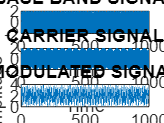

subplot(3,1,3);
plot(t,Modulated_signal);
title("MODULATED SIGNAL");
xlabel("Time");
ylabel("Amplitude");
grid;


figure
pspectrum(Modulated_signal,bandwidth)
hold

Current plot held


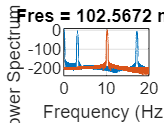

pspectrum(Carrier,bandwidth)

## Introduction to Signal Analyzer - Filter Implementation to extract Single Side Band Signal 

signalAnalyzer(Modulated_signal,Carrier);

[Introduction to Signal Analyzer App & Extraction of Single Side Band Signal](matlab:open('./SSB in SignalAnalyzer app.mldatx'))